# Behavioural results from scanning sessions

clc; clear all; close all;
data_struct = loadData();

%For this analysis, we're only interested in scanning sessions.
subjects = {'01RoYi','02XiHo','04NiSi','06KuSh','07AnWo'};

## Performance

Plotting run-wise accuracy for discrimination and detection separately. Each run is 40 trials of each task, so run-wise measures are relatively noisy.

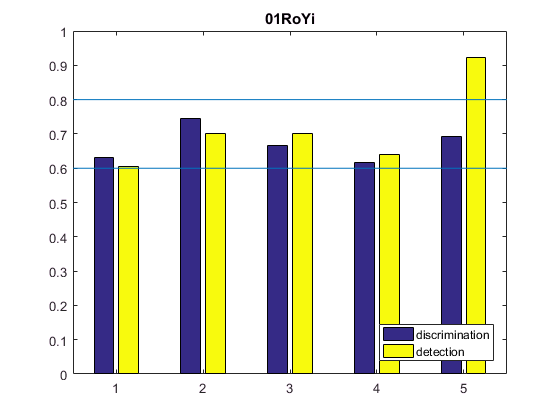

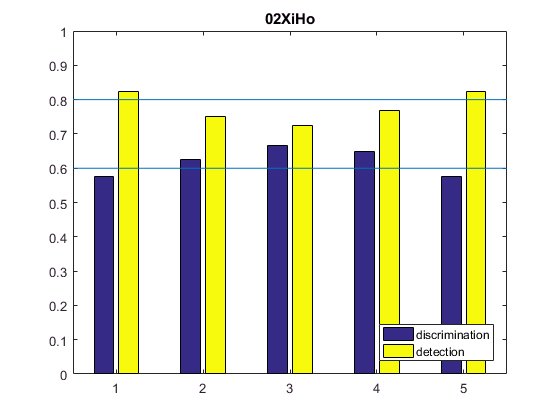

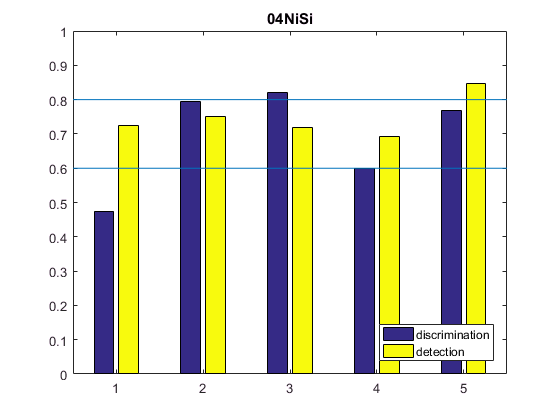

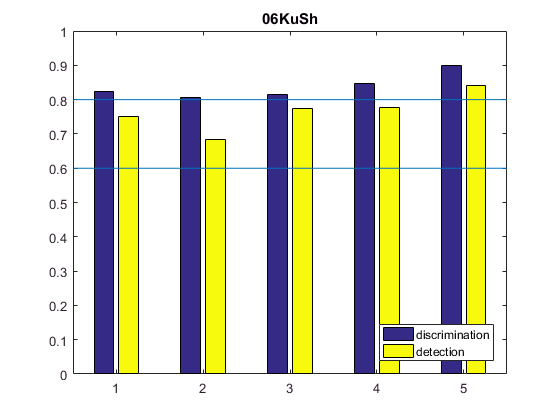

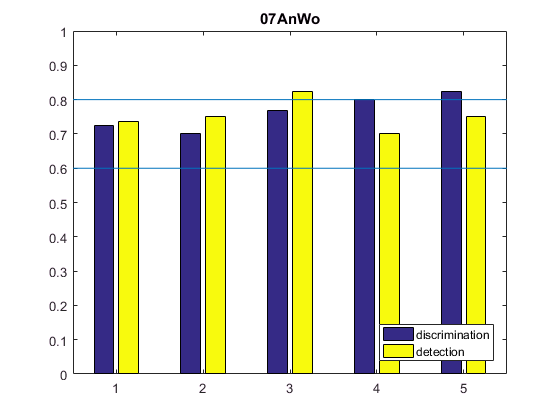

for s=1:length(subjects)
    subject = data_struct(subjects{s});
    performance = [];
    for trial_num = 1:40:161
        performance = [performance; ...
            nanmean(subject.DisCorrect(trial_num:trial_num+39)),...
            nanmean(subject.DetCorrect(trial_num:trial_num+39))];
    end
    figure;
    b = bar(performance);
    title(subjects{s})
    refline(0,0.6);
    refline(0,0.8);
    ylim([0,1]);
    legend('discrimination','detection','Location','southeast')
    
end

## Bias

Plotting run-wise response bias - i.e., the general tendency to respond 'yes' (detection) or 'clockwise' (discrimination).

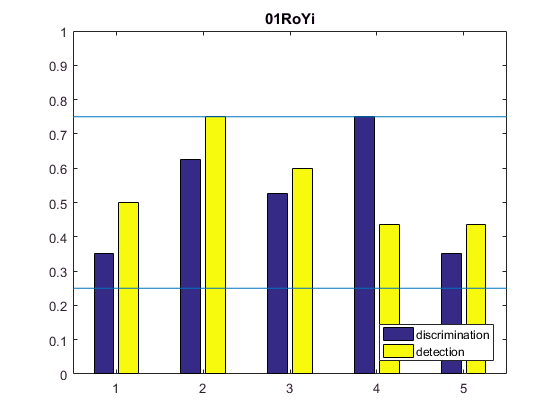

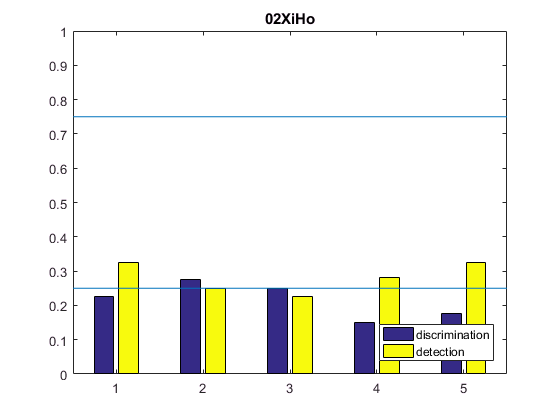

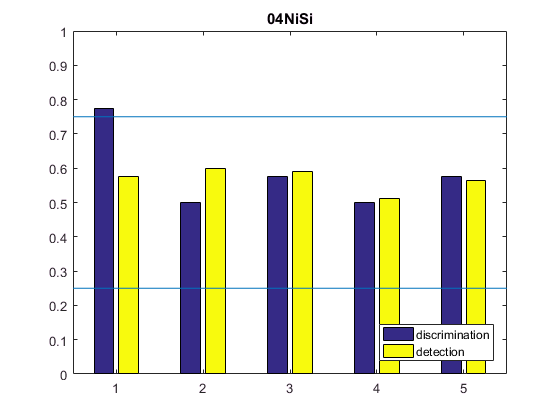

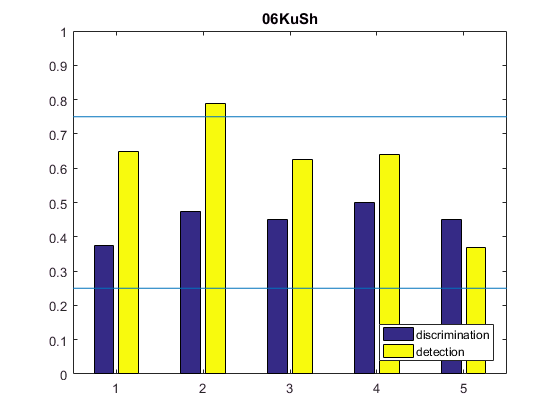

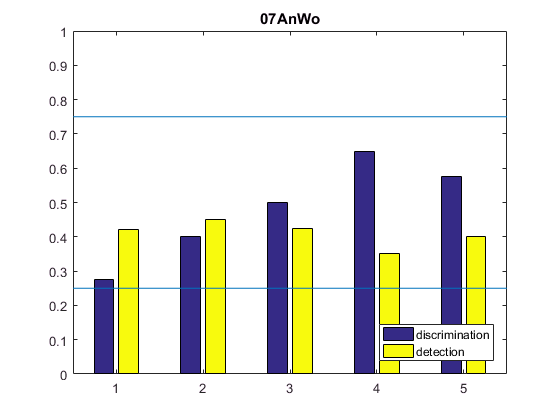

for s=1:length(subjects)
    subject = data_struct(subjects{s});
    performance = [];
    for trial_num = 1:40:161
        performance = [performance; ...
            nanmean(subject.DisResp(trial_num:trial_num+39)),...
            nanmean(subject.DetResp(trial_num:trial_num+39))];
    end
    figure;
    bar(performance)
    title(subjects{s})
    refline(0,0.75);
    refline(0,0.25);
    ylim([0,1]);
    legend('discrimination','detection','Location','southeast')
    
end

## Confidence Ratings

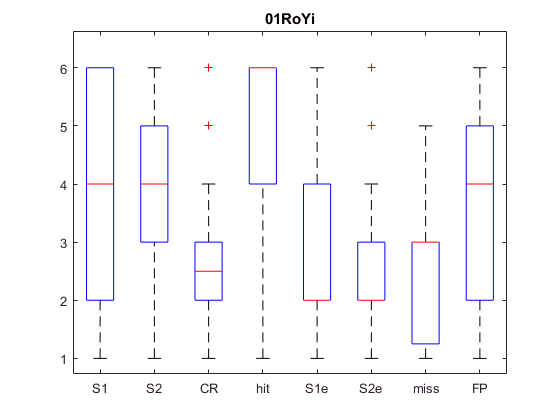

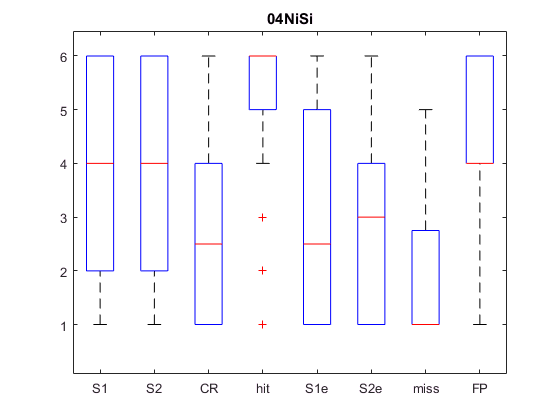

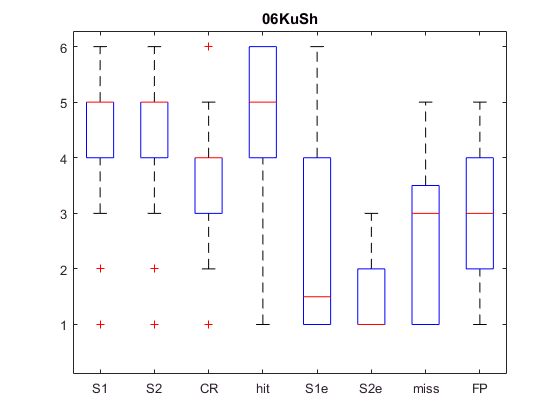

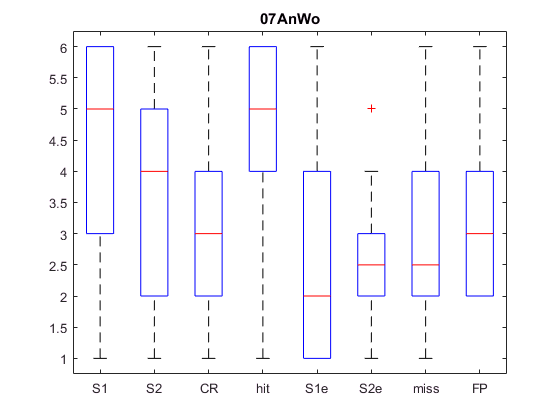

for s=1:length(subjects)
    subject = data_struct([subjects{s}]);
    trial_types = [subject.DisResp(subject.DisCorrect==1);...%%CORRECT RESPONSES
        2+subject.DetResp(subject.DetCorrect==1);...
        4+subject.DisResp(subject.DisCorrect==0);...%%INCORRECT RESPONSES
        6+subject.DetResp(subject.DetCorrect==0)];
    if numel(unique(trial_types))==8
        figure;
        title(subjects{s})
        hold on
        boxplot([subject.DisConf(subject.DisCorrect==1); %%CORRECT RESPONSES
            subject.DetConf(subject.DetCorrect==1);...
            subject.DisConf(subject.DisCorrect==0); %%INCORRECT RESPONSES
            subject.DetConf(subject.DetCorrect==0)],...
            ...
            trial_types, ...
            'Labels', {'S1','S2','CR','hit', 'S1e','S2e', 'miss', 'FP'})
    end

end